
clear;

csvFolderName = "RandomWalk";
clockTimeLimit = 30; % 体験時間 (s)
period = 3; % 歩行周期 (s)

legForwardTimeRate = 3; % 足スライダ前進 時間比
legBackwardTimeRate = 4; % 足スライダ後退 時間比

stockForwardTimeRate = 3; % ストックスライダ前進 時間比
stockBackwardTimeRate = 4; % ストックスライダ後退 時間比

upTimeRate = 1; % 伸縮 持ち上げ 時間比
downTimeRate = 1; % 伸縮 降下 時間比

stockFlyingTimeRate = 3; % ストック空中時間比
stockGroundTimeRate = 4; % ストック接地時間比

tiltBackwardTimeRate = stockForwardTimeRate;
tiltForwardTimeRate = stockBackwardTimeRate;

liftLength = 30; % 椅子 リフト長 単位 (mm)
pedalLength = 40; % ペダル長 単位 (mm)
seatSlideForwardLength = 100; % 椅子 スライド長 単位 (mm)
seatSlideBackwardLength = 50; % 椅子 スライド長 単位 (mm)
extendLength = 100; % 伸縮長 単位 (mm)
stockSlideForwardLength = 150; % ストック スライド前方向長 単位 (mm)
stockSlideBackwardLength = 100; % ストック スライド後方向長 単位 (mm)
tiltBackwardDeg = 5; % ストック 後傾角度 (deg)
tiltForwardDeg = -10; % ストック 前傾角度 (deg)

stockStartTime = 0;
waitTime = period/2;


stopTime = clockTimeLimit;
stopTable = table(stopTime);
writetable(stopTable, csvFolderName + '\' + "stop.csv");

randdt = 1.5;

椅子 リフト

L = liftLength; % スライド長 単位 (mm)
clockTime = 0;
deltaTime = rand + randdt;
while clockTime(end,1) < clockTimeLimit - 2
    clockTime(end+1,1) = clockTime(end,1) + deltaTime(end,1);
    deltaTime(end+1,1) = rand + randdt;
end

absolutePosition = L*rand(size(clockTime));
useStiffness = zeros(size(clockTime));

lifter = table(clockTime, deltaTime, absolutePosition, useStiffness)

lifter = 15×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

          0       2.3147           4.2566              0      
     2.3147       2.4058           12.653              0      
     4.7205        1.627           27.472              0      
     6.3475       2.4134           23.766              0      
     8.7609       2.1324           28.785              0      
     10.893       1.5975           19.672              0      
     12.491       1.7785           1.0714              0      
     14.269       2.0469           25.474              0      
     16.316       2.4575            28.02              0      
     18.774       2.4649           20.362              0      
     21.239       1.6576           22.732              0      
     22.896       2.4706           22.294              0      
     25.367       2.4572           11.767              0      
     27.824       1.9854          

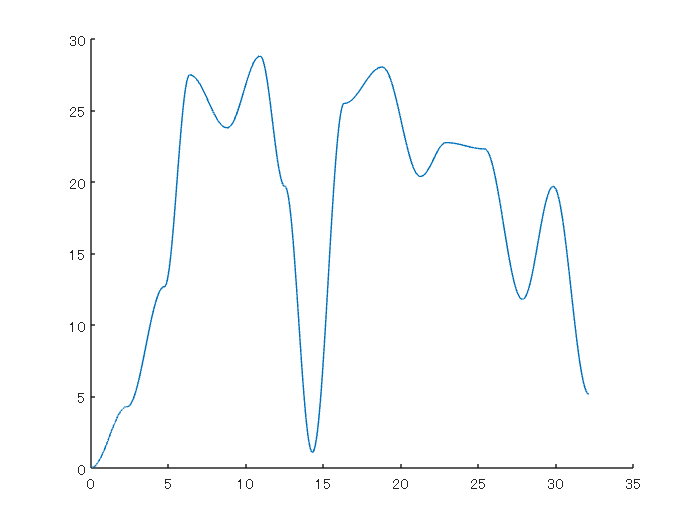

writetable(lifter, csvFolderName + '\' + "lifter.csv");
figure;
[lifter_x, lifter_t] = showGraph(clockTime, deltaTime, absolutePosition);

左ペダル

L = pedalLength; % スライド長 単位 (mm)
clockTime = 0;
deltaTime = rand + randdt;
while clockTime(end,1) < clockTimeLimit - 2
    clockTime(end+1,1) = clockTime(end,1) + deltaTime(end,1);
    deltaTime(end+1,1) = rand + randdt;
end

absolutePosition = L*rand(size(clockTime));
useStiffness = zeros(size(clockTime));

leftPedal = table(clockTime, deltaTime, absolutePosition, useStiffness)

leftPedal = 16×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

          0        2.206           17.823              0      
      2.206       1.5318           25.853              0      
     3.7379       1.7769           28.375              0      
     5.5148       1.5462           30.187              0      
      7.061       1.5971           11.041              0      
     8.6581       2.3235           27.188              0      
     10.982       2.1948           26.204              0      
     13.176       1.8171           6.5045              0      
     14.993       2.4502           4.7599              0      
     17.444       1.5344           19.935              0      
     18.978       1.9387            38.39              0      
     20.917       1.8816           13.615              0      
     22.798       2.2655           23.411              0      
     25.064       2.2952       

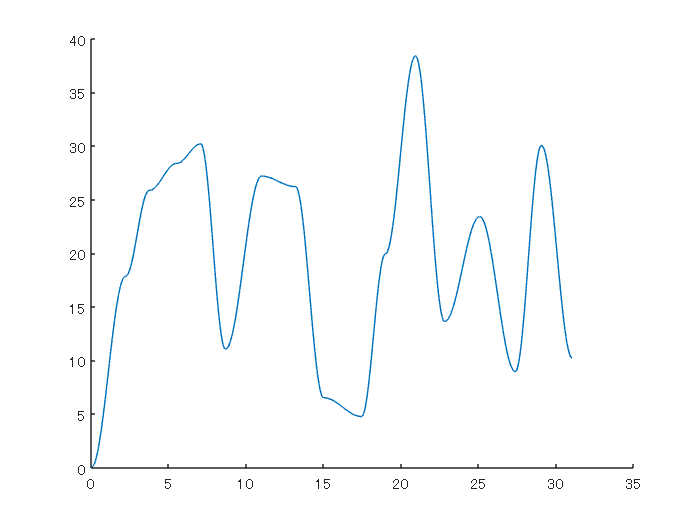

writetable(leftPedal, csvFolderName + '\' + "leftPedal.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
figure;
[leftPedal_x, leftPedal_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ペダル

L = pedalLength; % スライド長 単位 (mm)
clockTime = 0;
deltaTime = rand + randdt;
while clockTime(end,1) < clockTimeLimit - 2
    clockTime(end+1,1) = clockTime(end,1) + deltaTime(end,1);
    deltaTime(end+1,1) = rand + randdt;
end

absolutePosition = L*rand(size(clockTime));
useStiffness = zeros(size(clockTime));

rightPedal = table(clockTime, deltaTime, absolutePosition, useStiffness)

rightPedal = 15×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

          0        2.006           10.043              0      
      2.006       2.1991           24.642              0      
      4.205       2.3909           18.932              0      
     6.5959       2.4593           14.066              0      
     9.0552       2.0472           33.233              0      
     11.102       1.6386           23.411              0      
     12.741       1.6493           21.989              0      
      14.39       1.7575           36.688              0      
     16.148       2.3407           11.434              0      
     18.489       1.7543           30.288              0      
     20.243       2.3143           30.149              0      
     22.557       1.7435           15.218              0      
     24.301       2.4293           22.713              0      
      26.73         1.85      

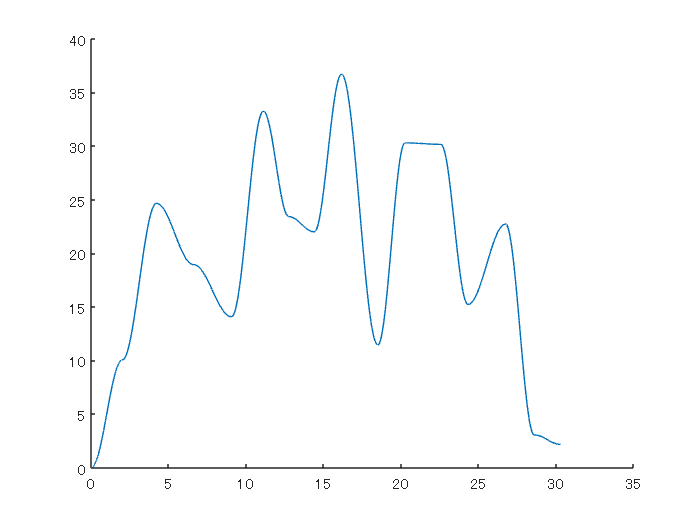

writetable(rightPedal, csvFolderName + '\' + "rightPedal.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
figure;
[rightPedal_x, rightPedal_t] = showGraph(clockTime, deltaTime, absolutePosition);

椅子　左　スライダ

clockTime = 0;
deltaTime = rand + randdt;
while clockTime(end,1) < clockTimeLimit - 2
    clockTime(end+1,1) = clockTime(end,1) + deltaTime(end,1);
    deltaTime(end+1,1) = rand + randdt;
end
absolutePosition = (seatSlideForwardLength + seatSlideBackwardLength) *rand(size(clockTime)) - seatSlideBackwardLength;
useStiffness = zeros(size(clockTime));

seatLeftSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)

seatLeftSlider = 16×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

          0       2.0308           53.382              0      
     2.0308       2.2792           62.223              0      
       4.31        2.434           17.581              0      
      6.744       1.6299          -37.427              0      
     8.3739       2.0688          -15.653              0      
     10.443       1.9694           87.001              0      
     12.412       1.5119          -27.143              0      
     13.924       1.8371           73.873              0      
     15.761       1.6622           30.751              0      
     17.423       2.2943            99.42              0      
     19.718       1.8112          -38.274              0      
     21.529       2.0285           16.402              0      
     23.557       1.6656          -34.002              0      
     25.223        2.102  

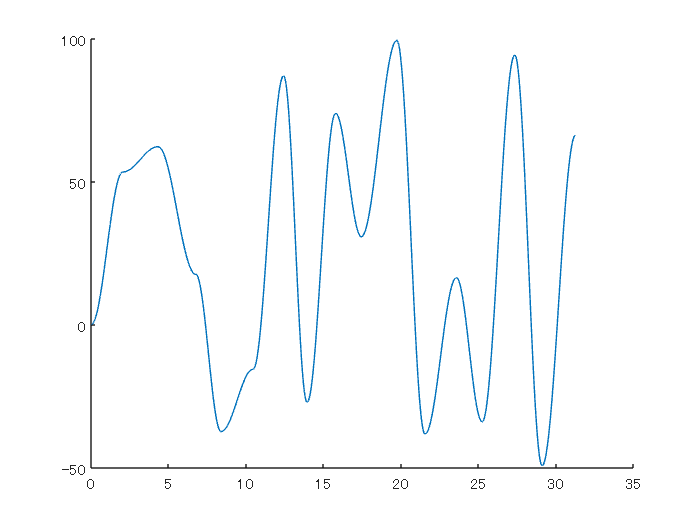

writetable(seatLeftSlider, csvFolderName + '\' + "seatLeftSlider.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
figure;
[seatLeftSlider_x, seatLeftSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);

椅子　右　スライダ

clockTime = 0;
deltaTime = rand + randdt;
while clockTime(end,1) < clockTimeLimit - 2
    clockTime(end+1,1) = clockTime(end,1) + deltaTime(end,1);
    deltaTime(end+1,1) = rand + randdt;
end
absolutePosition = (seatSlideForwardLength + seatSlideBackwardLength) *rand(size(clockTime)) - seatSlideBackwardLength;
useStiffness = zeros(size(clockTime));

seatRightSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)

seatRightSlider = 16×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

          0       2.3173           77.955              0      
     2.3173       2.3687           43.308              0      
      4.686       1.5844           2.6429              0      
     6.2704       1.8998           26.987              0      
     8.1702       1.7599           10.271              0      
     9.9301       2.3001          -38.605              0      
      12.23       1.9314          -14.013              0      
     14.162       2.4106          -31.502              0      
     16.572       1.6818          -22.414              0      
     18.254       1.7638          -14.007              0      
     20.018       1.6455            12.59              0      
     21.663       1.6361          -42.552              0      
     23.299       2.3693           85.407              0      
     25.669       2.0797 

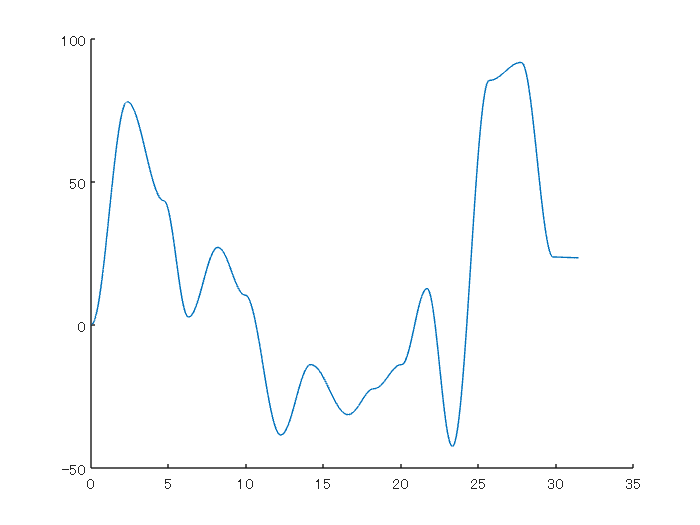

writetable(seatRightSlider, csvFolderName + '\' + "seatRightSlider.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
figure;
[seatRightSlider_x, seatRightSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);

左ストックの伸縮　登山

L = extendLength; % スライド長 単位 (mm)
clockTime = 0;
deltaTime = rand + randdt;
while clockTime(end,1) < clockTimeLimit - 2
    clockTime(end+1,1) = clockTime(end,1) + deltaTime(end,1);
    deltaTime(end+1,1) = rand + randdt;
end
absolutePosition = L*rand(size(clockTime));
useStiffness = zeros(size(clockTime));

stockLeftExtend = table(clockTime, deltaTime, absolutePosition, useStiffness)

stockLeftExtend = 16×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

          0       1.8377           82.119              0      
     1.8377       2.4001           1.5403              0      
     4.2378       1.8692           4.3024              0      
      6.107       1.6112           16.899              0      
     7.7182       2.2803           64.912              0      
     9.9985       1.8897           73.172              0      
     11.888       1.7417           64.775              0      
      13.63       1.9039           45.092              0      
     15.534       1.5965           54.701              0      
      17.13        1.632           29.632              0      
     18.762       2.4421           74.469              0      
     21.204       2.4561           18.896              0      
      23.66       2.0752           68.678              0      
     25.736       1.5598 

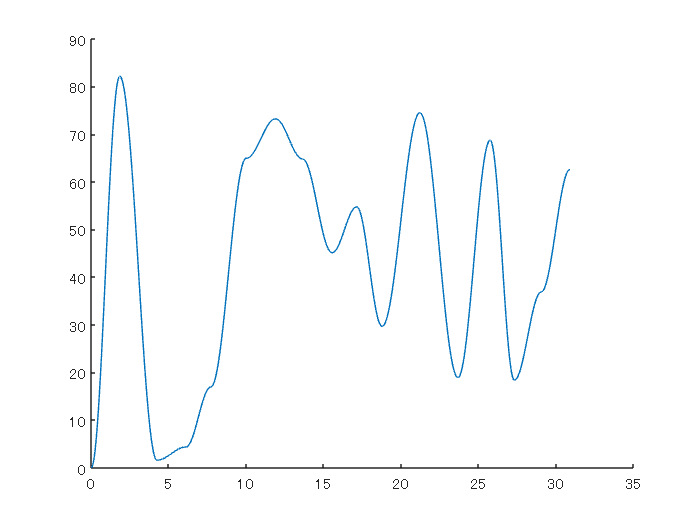

writetable(stockLeftExtend, csvFolderName + '\' + "stockLeftExtend.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
figure;
[stockLeftExtend_x, stockLeftExtend_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ストックの伸縮　登山


L = extendLength; % スライド長 単位 (mm)
clockTime = 0;
deltaTime = rand + randdt;
while clockTime(end,1) < clockTimeLimit - 2
    clockTime(end+1,1) = clockTime(end,1) + deltaTime(end,1);
    deltaTime(end+1,1) = rand + randdt;
end
absolutePosition = L*rand(size(clockTime));
useStiffness = zeros(size(clockTime));

stockRightExtend = table(clockTime, deltaTime, absolutePosition, useStiffness)

stockRightExtend = 15×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

          0       2.2802           53.283              0      
     2.2802       1.5811           35.073              0      
     3.8614       2.4294             93.9              0      
     6.2907       2.2757           87.594              0      
     8.5665       1.9868           55.016              0      
     10.553       1.9359           62.248              0      
     12.489       1.9468           58.704              0      
     14.436       1.8063           20.774              0      
     16.242       2.0085           30.125              0      
     18.251       2.0108           47.092              0      
     20.262       2.3176           23.049              0      
     22.579       2.2948           84.431              0      
     24.874       2.1443           19.476              0      
     27.018       1.8786

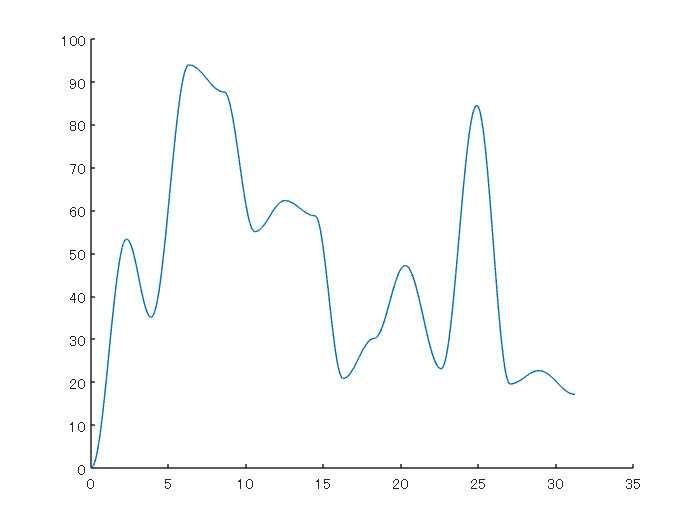

writetable(stockRightExtend, csvFolderName + '\' + "stockRightExtend.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
figure;
[stockRightExtend_x, stockRightExtend_t] = showGraph(clockTime, deltaTime, absolutePosition);

左ストックのスライダ

clockTime = 0;
deltaTime = rand + randdt;
while clockTime(end,1) < clockTimeLimit - 2
    clockTime(end+1,1) = clockTime(end,1) + deltaTime(end,1);
    deltaTime(end+1,1) = rand + randdt;
end
absolutePosition = (stockSlideForwardLength + stockSlideBackwardLength)*rand(size(clockTime)) - stockSlideBackwardLength;
useStiffness = zeros(size(clockTime));

stockLeftSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)

stockLeftSlider = 16×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

          0       1.7277          -44.563              0      
     1.7277       1.9357          -70.646              0      
     3.6634       1.8111          -25.831              0      
     5.4745       2.4234          -20.305              0      
     7.8978       1.9302           6.0417              0      
     9.8281       1.6848           26.965              0      
     11.513       2.4049          -78.621              0      
     13.918       2.4797          -34.379              0      
     16.397       1.9389           100.25              0      
     18.336       1.6111          -92.695              0      
     19.947       1.7581           132.21              0      
     21.706       1.9087           82.583              0      
     23.614       2.0949           22.152              0      
     25.709       1.7622 

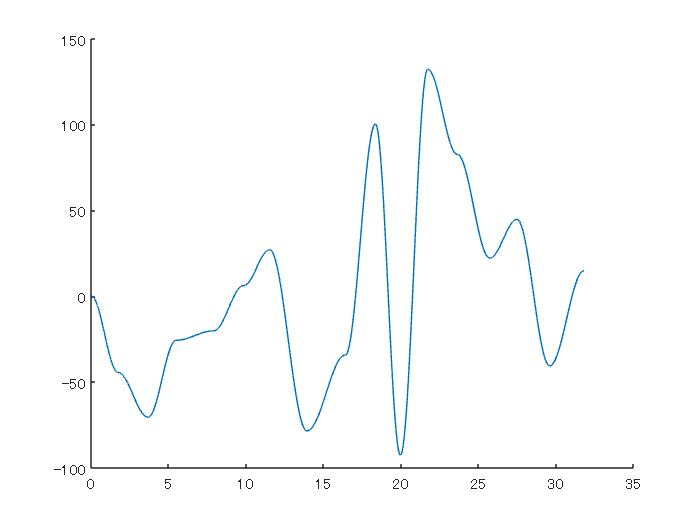

writetable(stockLeftSlider, csvFolderName + '\' + "stockLeftSlider.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
figure;
[stockLeftSlider_x, stockLeftSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ストックのスライダ

clockTime = 0;
deltaTime = rand + randdt;
while clockTime(end,1) < clockTimeLimit - 2
    clockTime(end+1,1) = clockTime(end,1) + deltaTime(end,1);
    deltaTime(end+1,1) = rand + randdt;
end
absolutePosition = (stockSlideForwardLength + stockSlideBackwardLength)*rand(size(clockTime)) - stockSlideBackwardLength;
useStiffness = zeros(size(clockTime));

stockLeftSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)

stockLeftSlider = 15×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

          0       2.4631          -34.532              0      
     2.4631       2.0468          -16.161              0      
     4.5099       2.0211           69.932              0      
      6.531       1.7316          -65.862              0      
     8.2626       1.9889           80.307              0      
     10.252       2.1241           -73.31              0      
     12.376       2.1791           63.439              0      
     14.555       1.8955           23.543              0      
      16.45       1.8674           94.763              0      
     18.318        2.488           78.759              0      
     20.806       1.5377           125.93              0      
     22.343       2.3852           122.73              0      
     24.729       2.4133          -16.459              0      
     27.142       2.2962 


stockRightSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)

stockRightSlider = 15×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

          0       2.4631          -34.532              0      
     2.4631       2.0468          -16.161              0      
     4.5099       2.0211           69.932              0      
      6.531       1.7316          -65.862              0      
     8.2626       1.9889           80.307              0      
     10.252       2.1241           -73.31              0      
     12.376       2.1791           63.439              0      
     14.555       1.8955           23.543              0      
      16.45       1.8674           94.763              0      
     18.318        2.488           78.759              0      
     20.806       1.5377           125.93              0      
     22.343       2.3852           122.73              0      
     24.729       2.4133          -16.459              0      
     27.142       2.2962

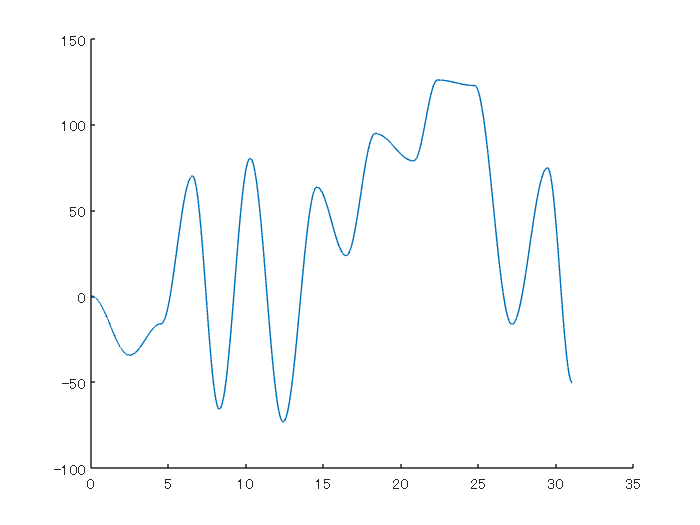

writetable(stockRightSlider, csvFolderName + '\' + "stockRightSlider.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
figure;
[stockRightSlider_x, stockRightSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);

左ストック 前後傾

LF = tiltForwardDeg; % 単位 (deg)
LB = tiltBackwardDeg; % 単位 (deg)
startClockTimeLeftTilt = stockStartTime + period/2 + waitTime - period/8; % 開始時刻 (s)
clockTimeB = 0; % 単位 (s)
clockTimeF = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
leftTiltDeltaTimeB = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
leftTiltDeltaTimeF = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
% leftTiltDelayTimeB = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) - leftTiltDeltaTimeF;
leftTiltDelayTimeB = 0;
leftTiltDelayTimeF = 0;
positionB = LB; % 単位 (deg)
positionF = LF; % 単位 (deg)

clockTimeBList = (startClockTimeLeftTilt + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = (startClockTimeLeftTilt + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeBList; clockTimeFList];
clockTime = tmp(:);
deltaTimeBList = leftTiltDeltaTimeB + 0*clockTimeBList;
deltaTimeFList = leftTiltDeltaTimeF + 0*clockTimeFList;
tmp = [deltaTimeBList; deltaTimeFList];
deltaTime = tmp(:);
positionBList = positionB + 0*clockTimeBList;
positionFList = positionF + 0*clockTimeFList;
tmp = [positionBList; positionFList];
absolutePosition = tmp(:);

% clockTime(end+1) = clockTimeLimit + period/2;
% deltaTime(end+1) = period/2;
% absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

leftTilt = table(clockTime, deltaTime, absolutePosition, useStiffness)

leftTilt = 18×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

      2.625       1.2857              5                0      
     3.9107       1.7143            -10                0      
      5.625       1.2857              5                0      
     6.9107       1.7143            -10                0      
      8.625       1.2857              5                0      
     9.9107       1.7143            -10                0      
     11.625       1.2857              5                0      
     12.911       1.7143            -10                0      
     14.625       1.2857              5                0      
     15.911       1.7143            -10                0      
     17.625       1.2857              5                0      
     18.911       1.7143            -10                0      
     20.625       1.2857              5                0      
     21.911       1.7143        

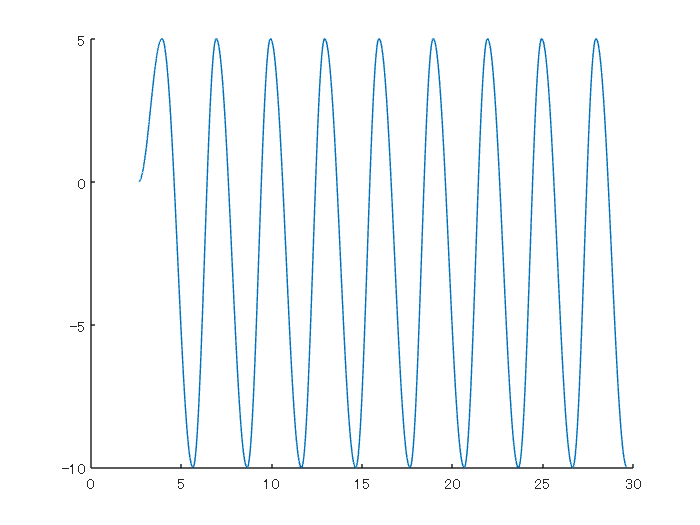

writetable(leftTilt, csvFolderName + '\' + "leftTilt.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
figure;
[leftTilt_x, leftTilt_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ストック 前後傾

LF = tiltForwardDeg; % 単位 (deg)
LB = tiltBackwardDeg; % 単位 (deg)
startClockTimeRightTilt = stockStartTime + waitTime - period/8; % 開始時刻 (s)
clockTimeB = 0; % 単位 (s)
clockTimeF = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
rightTiltDeltaTimeB = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
rightTiltDeltaTimeF = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
% rightTiltDelayTimeB = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) - rightTiltDeltaTimeF;
rightTiltDelayTimeB = 0;
rightTiltDelayTimeF = 0;
positionB = LB; % 単位 (deg)
positionF = LF; % 単位 (deg)

clockTimeBList = (startClockTimeRightTilt + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = (startClockTimeRightTilt + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeBList; clockTimeFList];
clockTime = tmp(:);
deltaTimeBList = rightTiltDeltaTimeB + 0*clockTimeBList;
deltaTimeFList = rightTiltDeltaTimeF + 0*clockTimeFList;
tmp = [deltaTimeBList; deltaTimeFList];
deltaTime = tmp(:);
positionBList = positionB + 0*clockTimeBList;
positionFList = positionF + 0*clockTimeFList;
tmp = [positionBList; positionFList];
absolutePosition = tmp(:);

% clockTime(end+1) = clockTimeLimit + period/2;
% deltaTime(end+1) = period/2;
% absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

rightTilt = table(clockTime, deltaTime, absolutePosition, useStiffness)

rightTilt = 20×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

      1.125       1.2857              5                0      
     2.4107       1.7143            -10                0      
      4.125       1.2857              5                0      
     5.4107       1.7143            -10                0      
      7.125       1.2857              5                0      
     8.4107       1.7143            -10                0      
     10.125       1.2857              5                0      
     11.411       1.7143            -10                0      
     13.125       1.2857              5                0      
     14.411       1.7143            -10                0      
     16.125       1.2857              5                0      
     17.411       1.7143            -10                0      
     19.125       1.2857              5                0      
     20.411       1.7143       

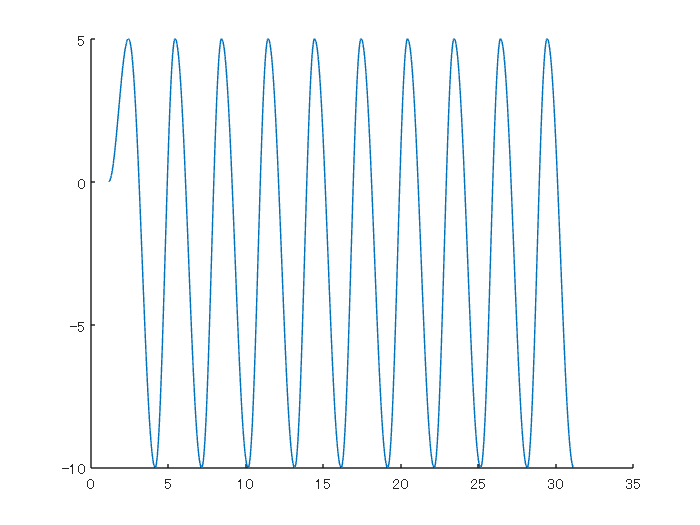

writetable(rightTilt, csvFolderName + '\' + "rightTilt.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
figure;
[rightTilt_x, rightTilt_t] = showGraph(clockTime, deltaTime, absolutePosition);

TiltCSV = table( ...
    period, tiltBackwardDeg, tiltForwardDeg, tiltBackwardTimeRate, tiltForwardTimeRate, startClockTimeLeftTilt, startClockTimeRightTilt, ...
    leftTiltDeltaTimeB, leftTiltDeltaTimeF, rightTiltDeltaTimeB, rightTiltDeltaTimeF, ...
    leftTiltDelayTimeB, leftTiltDelayTimeF, rightTiltDelayTimeB, rightTiltDelayTimeF ...
    )

TiltCSV = 1×15 table
    period    tiltBackwardDeg    tiltForwardDeg    tiltBackwardTimeRate    tiltForwardTimeRate    startClockTimeLeftTilt    startClockTimeRightTilt    leftTiltDeltaTimeB    leftTiltDeltaTimeF    rightTiltDeltaTimeB    rightTiltDeltaTimeF    leftTiltDelayTimeB    leftTiltDelayTimeF    rightTiltDelayTimeB    rightTiltDelayTimeF
    ______    _______________    ______________    ____________________    ___________________    ______________________    _______________________    __________________    __________________    ___________________    ___________________    __________________    __________________    ___________________    ___________________

      3              5                -10                   3                       4                     2.625                      1.125                   1.2857                1.7143                1.2857                 1.7143                   0                     0                      0                      0    

writetable(TiltCSV, csvFolderName + '\' + 'tilt.csv');

signal_lifter = timeseries(lifter_x, lifter_t, Name='lifter');
signal_leftPedal = timeseries(leftPedal_x, leftPedal_t, Name='leftPedal');
signal_rightPedal = timeseries(rightPedal_x, rightPedal_t, Name='rightPedal');
signal_seatLeftSlider = timeseries(seatLeftSlider_x, seatLeftSlider_t, Name='seatLeftSlider');
signal_seatRightSlider = timeseries(seatRightSlider_x, seatRightSlider_t, Name='seatRightSlider');
signal_stockLeftSlider = timeseries(stockLeftSlider_x, stockLeftSlider_t, Name='stockLeftSlider');
signal_stockRightSlider = timeseries(stockRightSlider_x, stockRightSlider_t, Name='stockRightSlider');
signal_stockLeftExtend = timeseries(stockLeftExtend_x, stockLeftExtend_t, Name='stockLeftExtend');
signal_stockRightExtend = timeseries(stockRightExtend_x, stockRightExtend_t, Name='stockRightExtend');
signal_leftTilt = timeseries(leftTilt_x, leftTilt_t, Name="leftTilt");
signal_rightTilt = timeseries(rightTilt_x, rightTilt_t, Name="rightTilt");

Scenario = Simulink.SimulationData.Dataset;

Scenario{1} = signal_lifter;
Scenario{2} = signal_leftPedal;
Scenario{3} = signal_rightPedal;
Scenario{4} = signal_seatLeftSlider;
Scenario{5} = signal_seatRightSlider;
Scenario{6} = signal_stockLeftExtend;
Scenario{7} = signal_stockRightExtend;
Scenario{8} = signal_stockLeftSlider;
Scenario{9} = signal_stockRightSlider;
Scenario{10} = signal_leftTilt;
Scenario{11} = signal_rightTilt;


% Scenario{2} = SignalStickRightPitch;
% Scenario{2}.Name = 'SignalStickRightPitch';
% Scenario{5} = signal_stockLeftPitch;
% Scenario{5}.Name = 'SignalStickLeftPitch';

save('../../../scenario.mat', 'Scenario');

sim("Simulink.slx");

clear;

function showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
    t = 0:0.001:deltaTime(1);
    x = absolutePosition(1)*(1 + cos(pi*t/deltaTime(1) + pi))/2;
    plot(t + clockTime(1), x);
    hold on;
    for idx = 2:length(clockTime)
        t = 0:0.01:deltaTime(idx);
        x = (absolutePosition(idx) - absolutePosition(idx-1)) * (1 + cos(pi*t/deltaTime(idx) + pi))/2 + absolutePosition(idx - 1);
        plot(t + clockTime(idx), x);
    end
end

function [ret_x, ret_t] = showGraph(clockTime, deltaTime, absolutePosition)
    % ret_t = [];
    t = (0:0.001:deltaTime(1))';
    x = absolutePosition(1)*(1 + cos(pi*t/deltaTime(1) + pi))/2;
    % plot(t + clockTime(1), x);
    ret_x = x;
    ret_t = t + clockTime(1);
    hold on;
    for idx = 2:length(clockTime)
        t = (0:0.01:deltaTime(idx))';
        x = (absolutePosition(idx) - absolutePosition(idx-1)) * (1 + cos(pi*t/deltaTime(idx) + pi))/2 + absolutePosition(idx - 1);
        % plot(t + clockTime(idx), x);
        ret_t = [ret_t; t + clockTime(idx)];
        ret_x = [ret_x; x];
    end
    plot(ret_t, ret_x);
end
